fileName = "DA_JW_1-6-Kern";
load(fileName+".mat");
load(fileName+"-Label.mat");
niftiwrite(volKern,fileName+".nii");
labels = uint8(labels);
niftiwrite(labels,fileName+"-Label.nii");

volReader = @(x) niftiread(x);
volds = imageDatastore(fileName+".nii",'FileExtensions','.nii','ReadFcn',volReader); %,'ReadFcn',volReader 
classNames = ["background","crack"];
pixelLabelID = [0 1];
pxds = pixelLabelDatastore(fileName+"-Label.nii", classNames,pixelLabelID,'FileExtensions','.nii','ReadFcn',volReader);

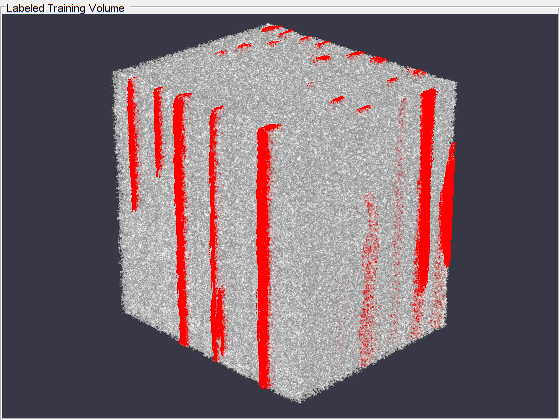

volume = preview(volds);
label = preview(pxds);

viewPnl = uipanel(figure,'Title','Labeled Training Volume');
hPred = labelvolshow(label,volume(:,:,:,1),'Parent',viewPnl, ...
    'LabelColor',[0 0 0;1 0 0]);
hPred.LabelVisibility(1) = 0;

patchSize = [116 116 116];
patchPerImage = 100;
miniBatchSize = 4;
patchds = randomPatchExtractionDatastore(volds,pxds,patchSize, ...
    'PatchesPerImage',patchPerImage);
patchds.MiniBatchSize = miniBatchSize;

patchPerImageVal = 30;
valds = randomPatchExtractionDatastore(volds,pxds,patchSize, ...
    'PatchesPerImage',patchPerImageVal);
valds.MiniBatchSize = miniBatchSize;

numChannels = 1;
inputPatchSize = [patchSize numChannels];
numClasses = 2;
[lgraph,outPatchSize] = unet3dLayers(inputPatchSize,numClasses,'ConvolutionPadding','valid');

dataSource = 'Training';
dsTrain = transform(patchds,@(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,dataSource));
dataSource = 'Validation';
dsVal = transform(valds,@(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,dataSource));

outputLayer = dicePixelClassificationLayer('Name','Output');
lgraph = replaceLayer(lgraph,'Segmentation-Layer',outputLayer);
options = trainingOptions('adam', ...
    'MaxEpochs',20, ...
    'InitialLearnRate',5e-4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',5, ...
    'LearnRateDropFactor',0.95, ...
    'ValidationData',dsVal, ...
    'ValidationFrequency',20, ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'MiniBatchSize',miniBatchSize);

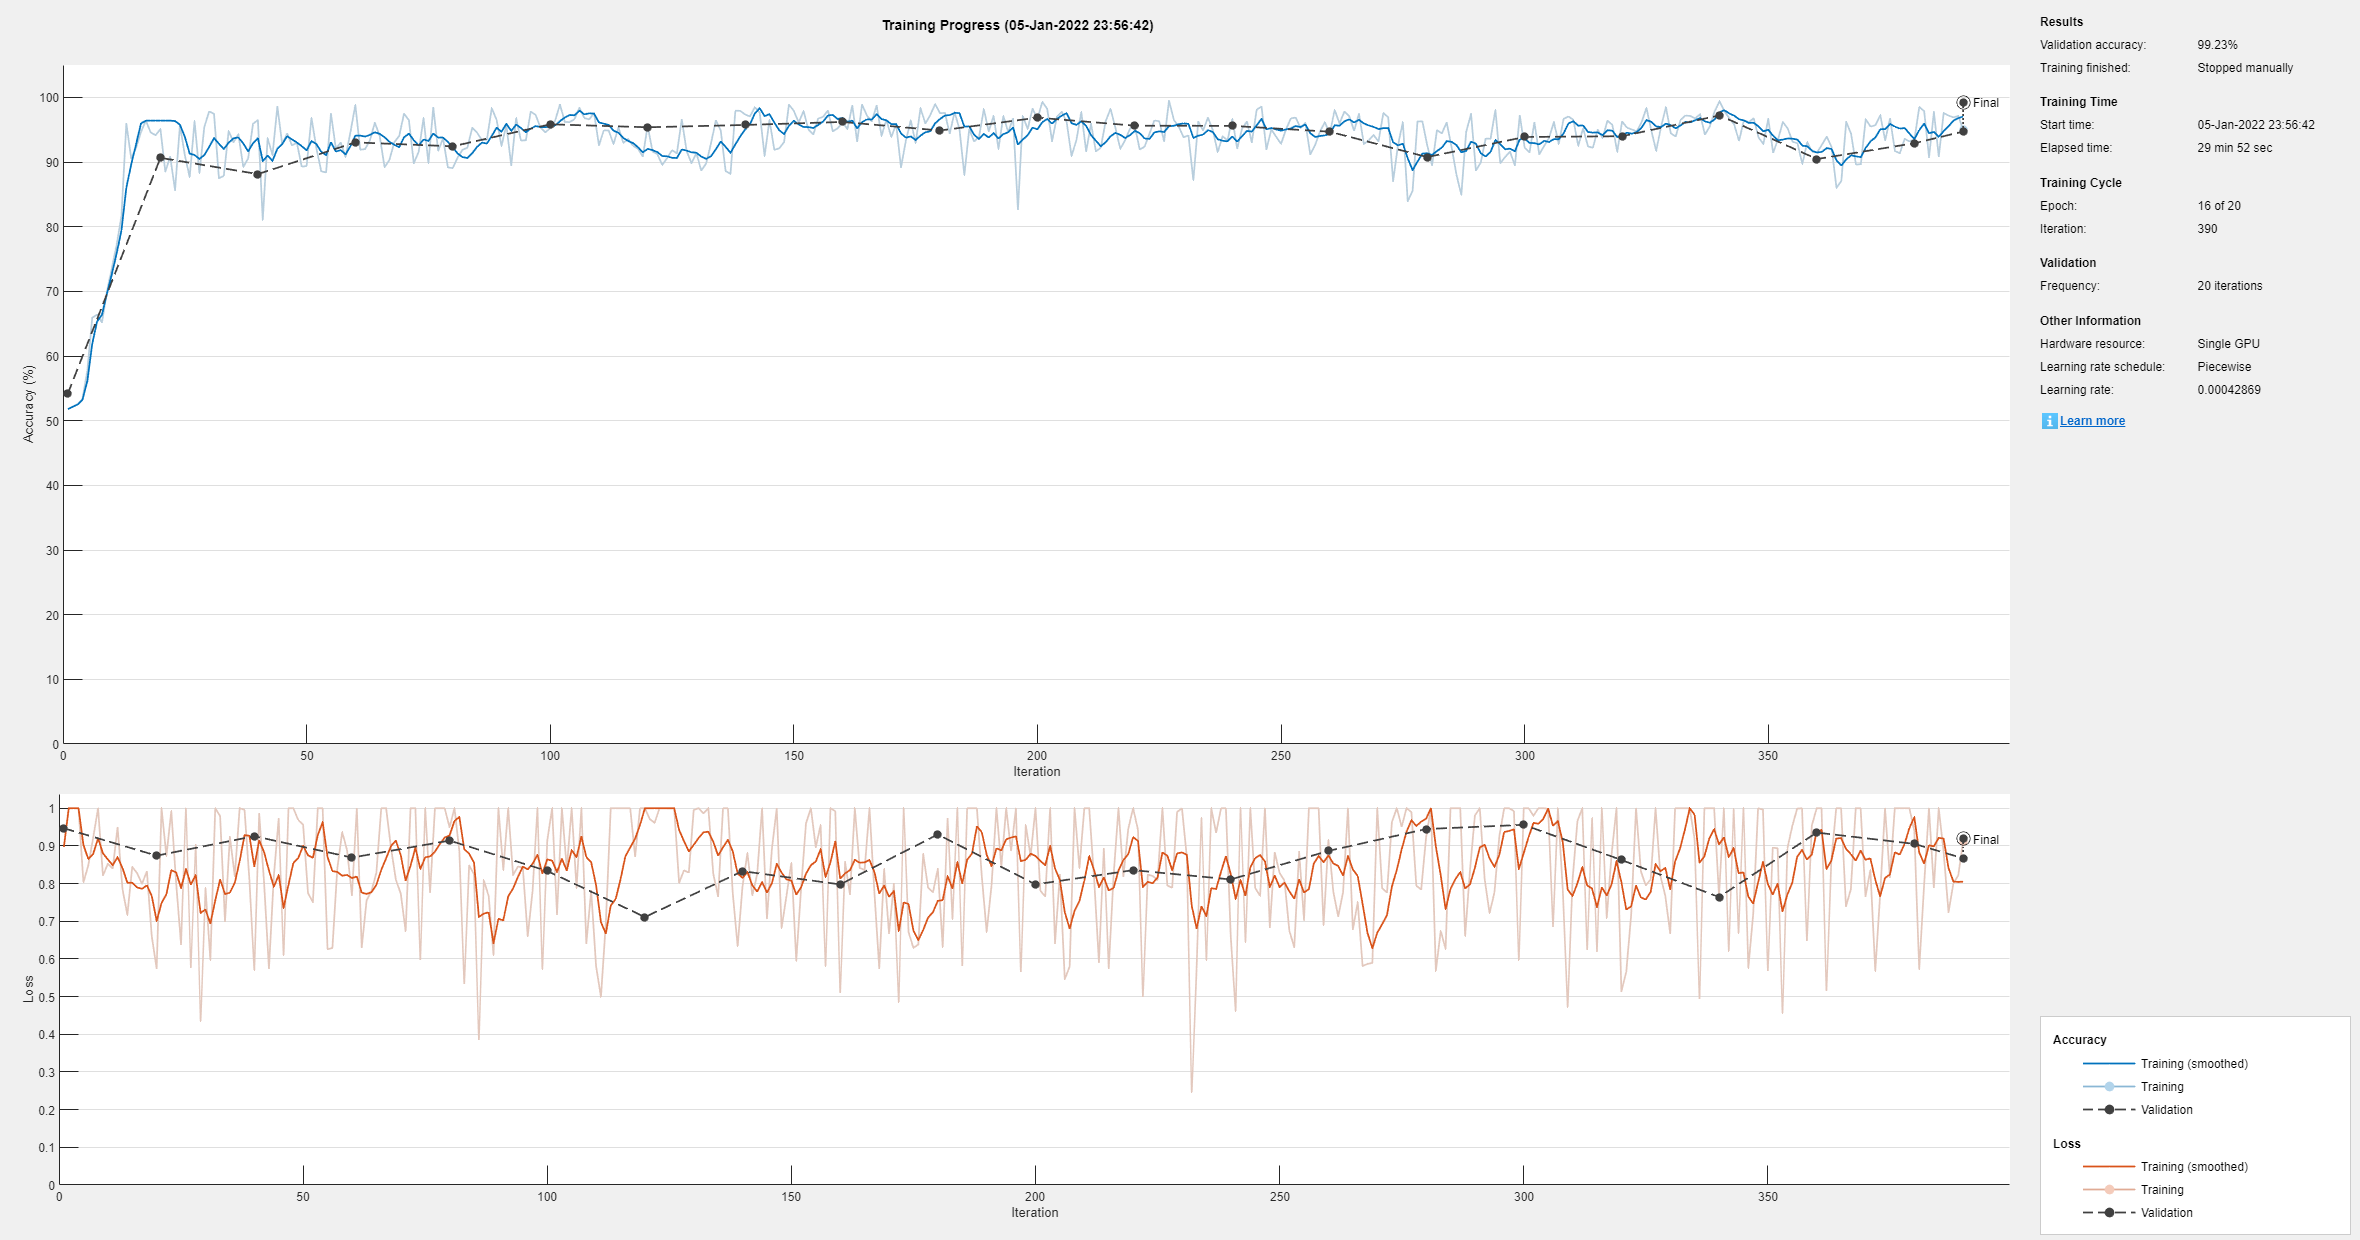

modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));
    [net,info] = trainNetwork(dsTrain,lgraph,options);

    save(strcat("trained3DUNet-",modelDateTime,"-Epoch-",num2str(options.MaxEpochs),".mat"),'net');

%patchseg = semanticseg(read(valds),net)


